% Definer teller og nevner for de forskjellige transferfunksjonene
teller = [1];
nevner = [0.01 0.05 1];
G = tf(teller, nevner)

G =
 
            1
  ---------------------
  0.01 s^2 + 0.05 s + 1
 
Continuous-time transfer function.
Model Properties



teller1 = [1];
nevner1 = [0.01 0.2 1];
G1 = tf(teller1, nevner1)

G1 =
 
           1
  --------------------
  0.01 s^2 + 0.2 s + 1
 
Continuous-time transfer function.
Model Properties



teller2 = [1];
nevner2 = [0.01 0.4 1];
G2 = tf(teller2, nevner2)

G2 =
 
           1
  --------------------
  0.01 s^2 + 0.4 s + 1
 
Continuous-time transfer function.
Model Properties



teller3 = [1];
nevner3 = [0.01 0 1];
G3 = tf(teller3, nevner3)

G3 =
 
       1
  ------------
  0.01 s^2 + 1
 
Continuous-time transfer function.
Model Properties


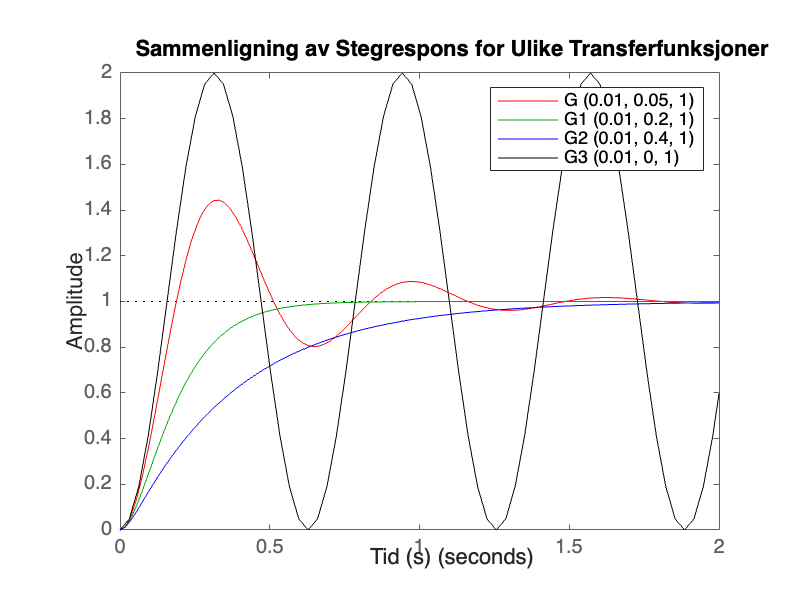


% Åpne en ny figur
figure;

% Bruk hold on for å beholde plottet åpent for flere kurver
hold on;

% Plot stegresponsene for hver transferfunksjon med spesifikke farger
step(G, 'r')    % Rød kurve for G
step(G1, 'g')   % Grønn kurve for G1
step(G2, 'b')   % Blå kurve for G2
step(G3, 'k')   % Svart kurve for G3

% Juster aksene etter behov
axis([0 2 0 2])

% Legg til tittel og akseetiketter
title('Sammenligning av Stegrespons for Ulike Transferfunksjoner')
xlabel('Tid (s)')
ylabel('Amplitude')

% Legg til en legende for å skille de ulike transferfunksjonene
legend('G (0.01, 0.05, 1)', 'G1 (0.01, 0.2, 1)', 'G2 (0.01, 0.4, 1)', 'G3 (0.01, 0, 1)')


% Slipp plottet
%hold off;
